First order system:

A = 2;
B = 1;

N = 5;
Q = 2;
R = 0.5;
sys = LTISystem('A',A,'B',B);

sys.x.max = [5];
sys.x.min = [-5 ];
sys.u.min = [-1.75];
sys.u.max = [1.75];
sys.x.penalty = QuadFunction(Q);
sys.u.penalty = QuadFunction(R);


K_matlab = sys.LQRGain

K_matlab = -1.7656


Qf = sys.LQRPenalty.weight

Qf = 3.7656



model.x.terminalPenalty = QuadFunction(Qf)

model = struct with fields:
    x: [1×1 struct]


model.x.terminalSet = sys.LQRSet

Iteration 1...
Iteration 2...


model = struct with fields:
    x: [1×1 struct]



controller = MPCController(sys, N)

MPC controller (horizon: 5)



empc = controller.toExplicit()

mpt_plcp: 11 regions
Explicit MPC controller (horizon: 5, regions: 11)


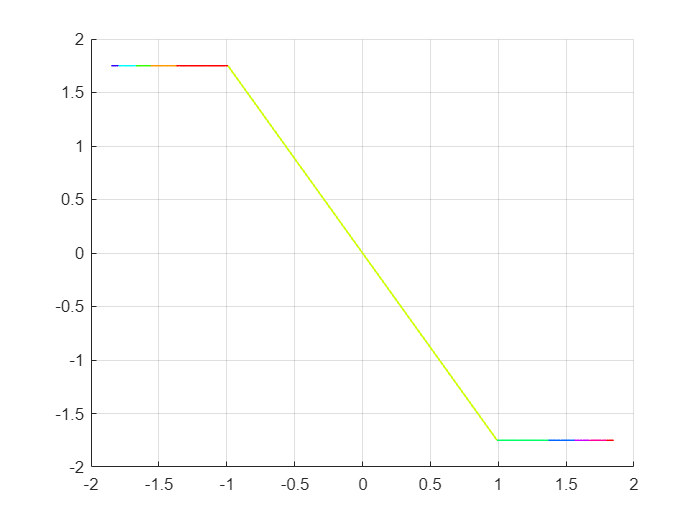


empc.feedback.fplot()